clc
clear
%% 参数
dt = 0.016;
t = 0:dt:49-dt;

a = (1.045-0.780)*rand() + 0.780;
omega = 0*(2-1.884)*rand() + 1.884;
phi = 2*pi*rand(1,1);
a1 = 1.045;
omega1 = 2;
fn =@(t) -a./omega *cos(omega*t+phi)+(2.090-a)*t;
theta = mod(fn(t)+ 0.0*pi*randn(1,length(t)),2*pi);
% 
% g = @(t) a1*sin(omega*t+phi)+2.090-a1+ 2*0.04*randn(1,length(t));
% g2 = @(t) a1*sin(omega1*t+phi)+2.090-a1+ 2*0.04*randn(1,length(t))
% theta = g(t);
disp(omega/(2*pi))

    0.2998



disp(omega1/(2*pi))

    0.3183



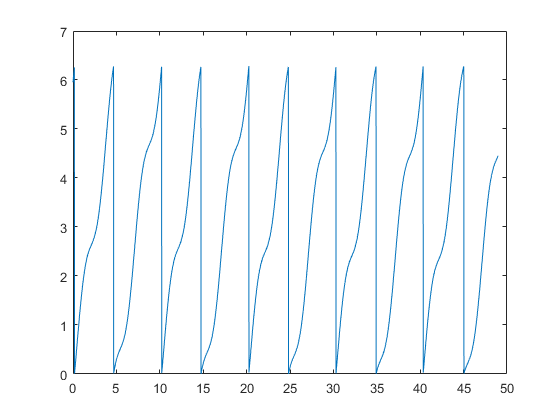

% f =@(x)sin(2*pi*0.5*x+1);
% theta = f(t);
plot(t,theta)

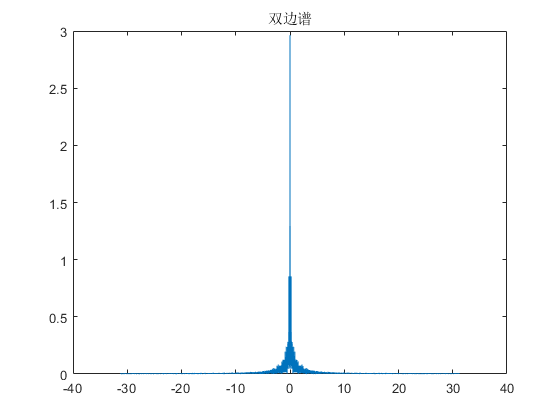


Fs = 1/dt;
N = length(t);

yy_t = fft(theta,N);
m = abs(fftshift(yy_t));
f = Fs/N ;
n = 0:N-1;
double_f = f*n - Fs/2;
plot(double_f,m/N);
title(["双边谱"])


yout = 2*abs(yy_t(1:N/2))/N; %单边谱是双变谱振幅的两倍
yout(1) = abs(yy_t(1))/N;
disp(2.090 -  yout(1))

   -0.8737



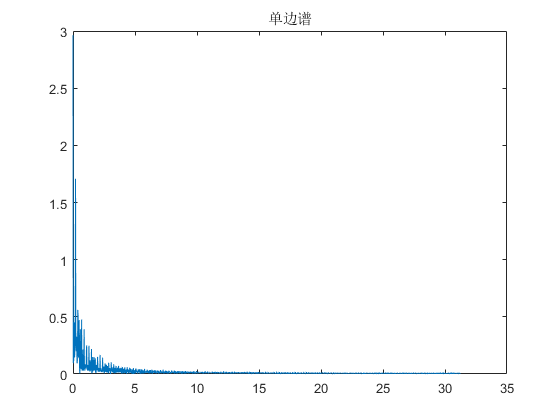

%分辨率
%0:f:Fs/2-f = f*n  n = 0:N-1
single_f = f*(0:N/2 - 1);
plot(single_f,yout)
title(["单边谱"])